# Homework 5 Problem 4

### *EE 261: FT & Its Applications*

#### *Noor Fakih*

### Part A: Produce the prompted figures

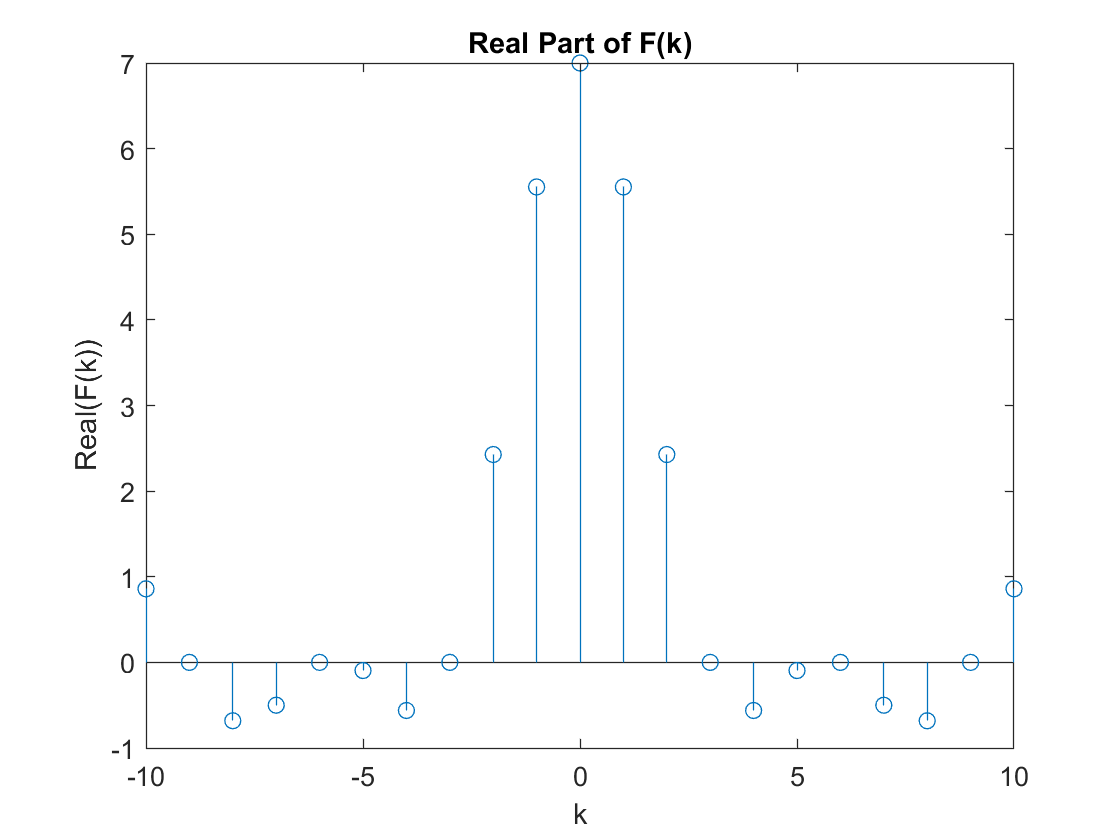

f = [0 0 0 0 0 0 0 1 1 1 1 1 1 1 0 0 0 0 0 0 0];
X = fftshift(fft(fftshift(f)));
stem([-10:10], real(X));
title('Real Part of F(k)')
xlabel('k'); ylabel('Real(F(k))');

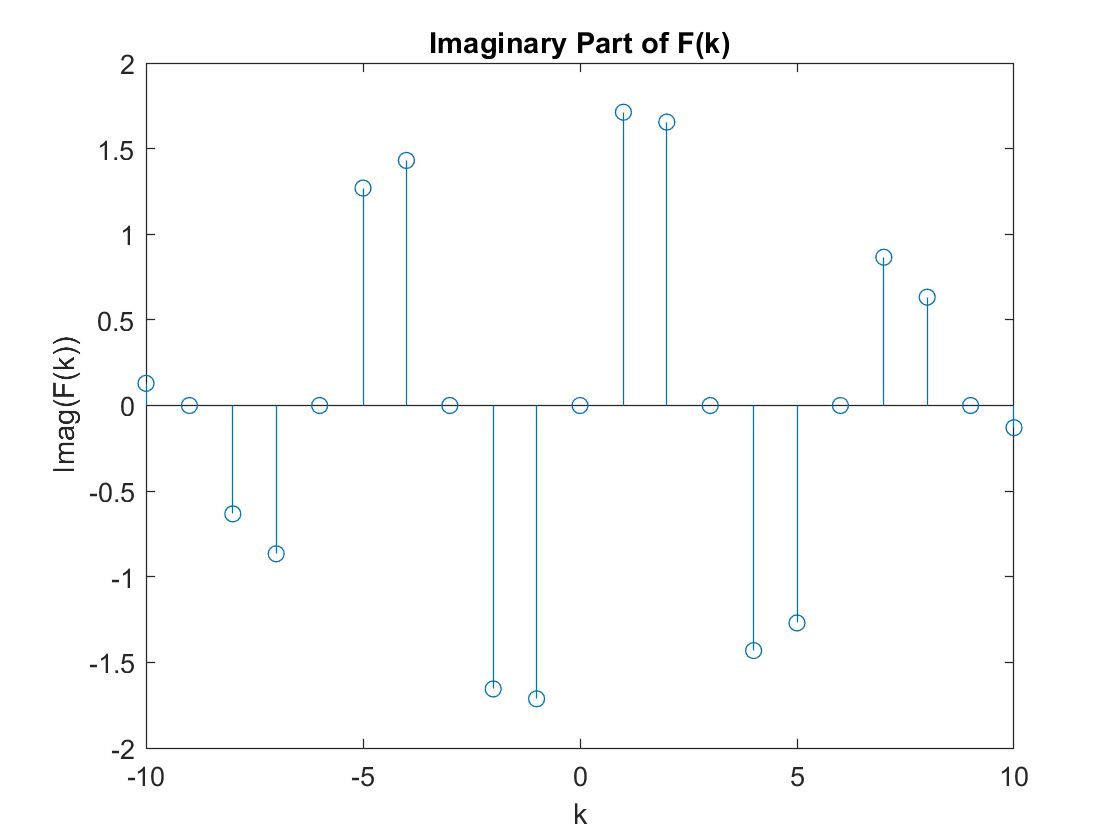

stem([-10:10], imag(X));
title('Imaginary Part of F(k)')
xlabel('k'); ylabel('Imag(F(k))');

### Part B: Is Professor Osgood right to object? If so, what is the basis of his objection, and produce the correct plot. If not, explain why the student is correct.

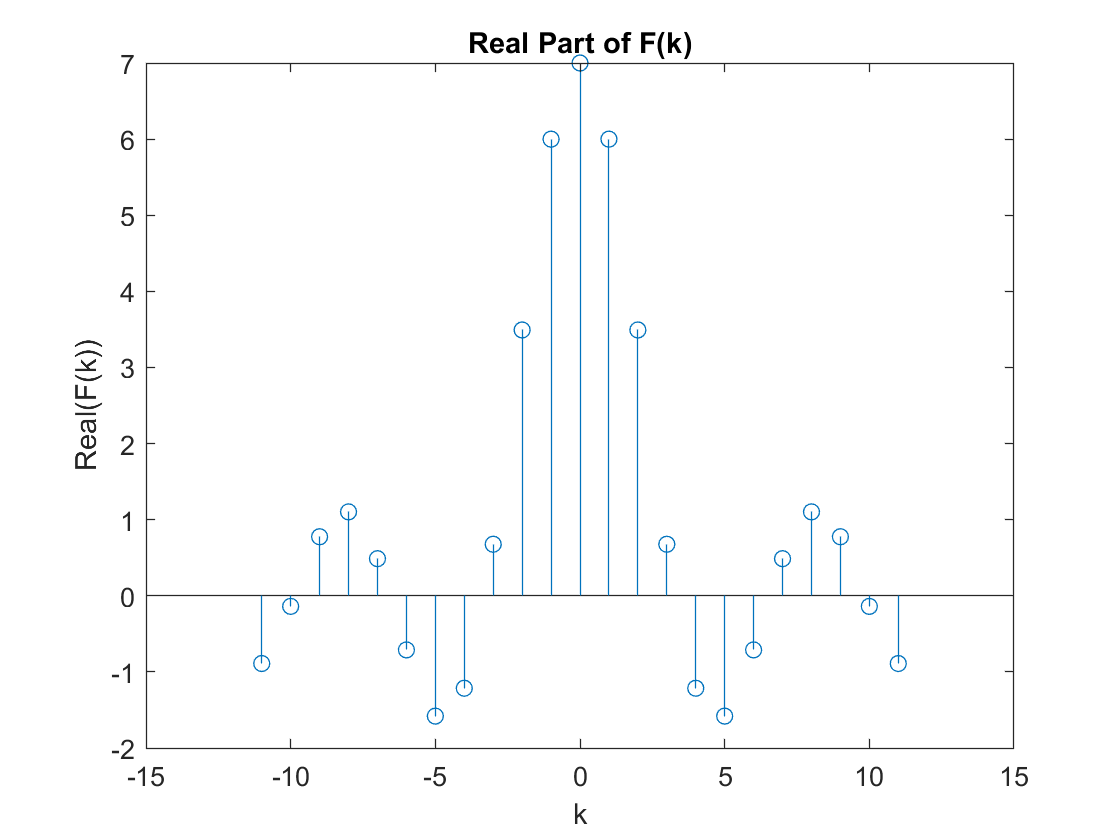

fcorr = [0 0 0 0 0 0 0 0 0 1 1 1 1 1 1 1 0 0 0 0 0 0 0];
Xcorr = fftshift(fft(fftshift(fcorr)));
stem([-11:11], real(Xcorr));
title('Real Part of F(k)')
xlabel('k'); ylabel('Real(F(k))');

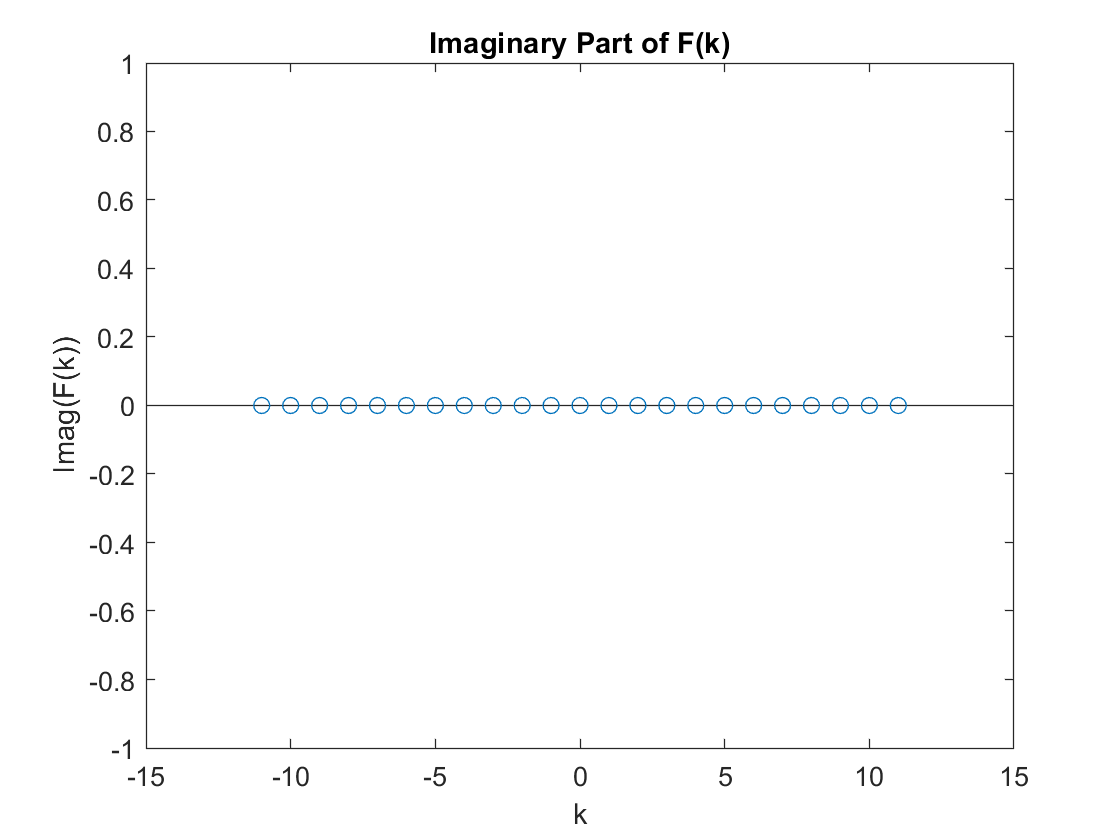

stem([-11:11],imag(Xcorr));
title('Imaginary Part of F(k)')
xlabel('k'); ylabel('Imag(F(k))');

Prof. Osgood is correct in objecting. In the original plots, they use fftshift which alters what is considered to be the center of the original array, f, and takes the array length divided by 2 + 1 to be the starting point of the array. The fix is to make sure that it is centered at that point (array length/2 +1), not starting at it, which is how we were able to get an F without an imaginary part.